### Get generating_data

mainFolderPath = strcat('Z:\Projects\РФФИ-Норвегия\Данные\', ...
    'Экспериментальные данные в лаборатории\', ...
    'Droplet freezing facility data\Generating droplets\');

data_name = 'GENERATING_DATA.csv';

data_path = strcat(mainFolderPath,data_name);

gen_df = readtable(data_path)

gen_df = 713×27 table
    test    crop      test_type       voltage    pressure    impulse_time      needle        nozzle      distance    calibrat_test    record_rate                                                                        comments                                                                        experiment_date       tester        video     pixel_size    old_flow_type    old_droplet_size    droplet_count    flow_type     droplet_size    sigma_droplet_size    starting_velocity    ending_velocity    fall_time    vertical_path    

### Get single-droplets

single_params = struct

single_params = struct with no fields.


single_params.five = gen_df(((gen_df.crop~=0) & (gen_df.droplet_size>0) & (strcmp(gen_df.old_flow_type,'single')))...
    & strcmp(gen_df.needle,'N01-1') & (gen_df.impulse_time == 5000),:)

single_params = struct with fields:
    five: [63×27 table]


single_params.four = gen_df(((gen_df.crop~=0) & (gen_df.droplet_size>0) & (strcmp(gen_df.old_flow_type,'single')))...
    & strcmp(gen_df.needle,'N01-1') & (gen_df.impulse_time == 4000),:)

single_params = struct with fields:
    five: [63×27 table]
    four: [48×27 table]


### Evaluate a Surface Fit

% surffit = struct
% surffit.five = fit([single_params.five.voltage, single_params.five.pressure], ...
%     single_params.five.droplet_size, 'poly23','normalize','on')
% surffit.four = fit([single_params.four.voltage, single_params.four.pressure], ...
%     single_params.four.droplet_size, 'poly23','normalize','on')

### Create meshgrid

% [Voltage,Pressure] = meshgrid((single_params.five.voltage), (single_params.five.pressure))

### Plot graphics

clf
plot_table = single_params.five

plot_table = 63×27 table
    test    crop      test_type       voltage    pressure    impulse_time     needle       nozzle     distance    calibrat_test    record_rate                                  comments                                   experiment_date       tester           video        pixel_size    old_flow_type    old_droplet_size    droplet_count    flow_type     droplet_size    sigma_droplet_size    starting_velocity    ending_velocity    fall_time    vertical_path    max_horizontal_deviation
    ____    <

bubblechart(plot_table.voltage,plot_table.pressure,...
    plot_table.droplet_size, plot_table.starting_velocity)
hold on
plot(plot_table.voltage,plot_table.pressure,...
    '.r')
% labels = cellstr(num2str(round(plot_table.droplet_size)));
% text(plot_table.voltage,plot_table.pressure,labels)
grid on
grid minor
xlabel('voltage, V')
xlim([floor(min(plot_table.voltage)/5)*5,ceil(max(plot_table.voltage)/5)*5])
xticks(floor(min(plot_table.voltage)/5)*5:5:ceil(max(plot_table.voltage)/5)*5);

ylabel('pressure, mbar')
ylim([floor(min(plot_table.pressure)/500)*500,ceil(max(plot_table.pressure)/500)*500])
yticks(floor(min(plot_table.pressure)/500)*500:500:ceil(max(plot_table.pressure)/500)*500);
bubblesize([5 40])
bubblelegend('Droplet size, um','Location','eastoutside')
h = colorbar

h =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0.0258 0.9960]
    FontSize: 9
    Position: [0.8572 0.1286 0.0381 0.7976]
       Units: 'normalized'

  Show all properties


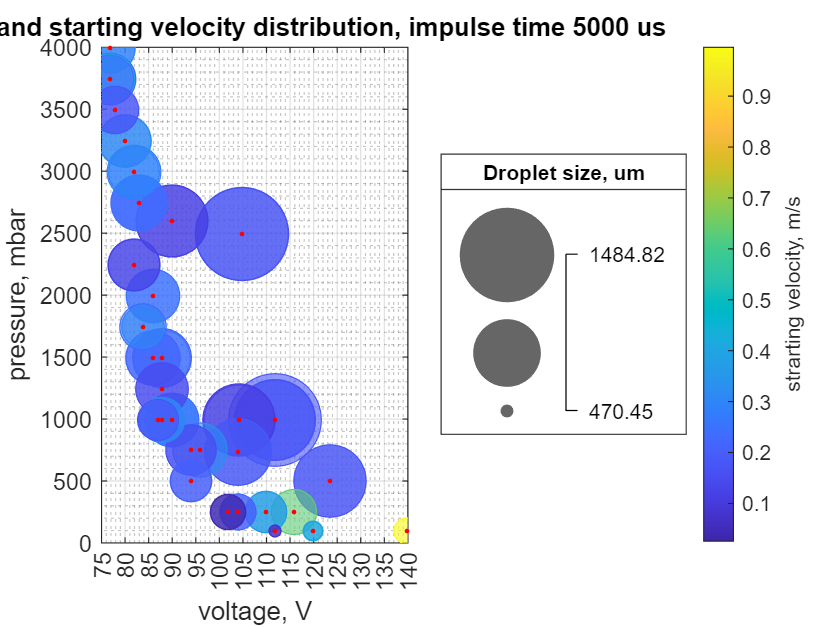

ylabel(h,'strarting velocity, m/s')
title('Droplet size and starting velocity distribution, impulse time 5000 us')

clf
plot_table = single_params.four

bubblechart(plot_table.voltage,plot_table.pressure,...
    plot_table.droplet_size, plot_table.starting_velocity)
hold on
plot(plot_table.voltage,plot_table.pressure,...
    '.r')
% labels = cellstr(num2str(round(plot_table.droplet_size)));
% text(plot_table.voltage,plot_table.pressure,labels)
grid on
grid minor
xlabel('voltage, V')
xlim([floor(min(plot_table.voltage)/5)*5,ceil(max(plot_table.voltage)/5)*5])
xticks(floor(min(plot_table.voltage)/5)*5:5:ceil(max(plot_table.voltage)/5)*5);

ylabel('pressure, mbar')
ylim([floor(min(plot_table.pressure)/500)*500,ceil(max(plot_table.pressure)/500)*500])
yticks(floor(min(plot_table.pressure)/500)*500:500:ceil(max(plot_table.pressure)/500)*500);
bubblesize([15 30])
bubblelegend('Droplet size, um','Location','eastoutside')
h = colorbar
ylabel(h,'strarting velocity, m/s')
title('Droplet size and starting velocity distribution, impulse time 4000 us') 